clearvars
freq_array = readtable('./ADC_Data/11-25-Python-Sweep-SEDE-1MHz-50%-900mV-100k-300k/freq_array.csv');
freq_array = table2array(freq_array);
freq_array = floor(freq_array);
%%% Remember to change this! if folder change
filepath = './ADC_Data/11-25-Python-Sweep-SEDE-1MHz-50%-900mV-100k-300k/';
% 1:freq, 2: SNR, 3: SNDR 4:SFDR
BigSet = zeros(length(freq_array),4);
% :length(freq_array)
for i = 1:length(freq_array)
    freq = num2str(freq_array(i));
    BigSet(i,1) = freq_array(i);
    filename = strcat(filepath,'SIN_',num2str(freq_array(i)),'Hz_900mV---CLK_1MHz_50%.csv');
    data = readtable(filename);
    data_dec = table2array(data);
    % data_dec = data_dec(data_dec ~= 0);
    data_bin = dec2bin(data_dec);
    data_EOC = str2num(data_bin(:,1));
    data_Code = str2num(data_bin(:,2:10));
    data_NewCode = size(length(data_Code),1);

    rising_edge_indices = find(diff(data_EOC) == 1) + 1;
    
    for k = 1:length(rising_edge_indices)
        index = rising_edge_indices(k);
        data_NewCode(k,1) = data_Code(index); 
    end

    data_NewDec = bin2dec(num2str(data_NewCode));

    Fs=1e6;
    num_segments=1;
    f_signal = freq_array(i);
    f_s = Fs;
    BW =500e3;
    sample_size=2^13;
    periodogram_length = sample_size / num_segments;
    fbin = f_s / periodogram_length;
    plotYN = 1; plotAll = 0; plotHold = 0; plotLin = 0; datNorm = 1;
    [sinusoid_power, data_minus_sinusoid_in_BW_power, SNDR, ENOB,HD2,HD3, SNR, SFDR] = ...
        plot_periodogram_SFDR(data_NewDec, periodogram_length, num_segments, f_signal, ...
        f_s, BW, plotAll, plotHold, plotYN, plotLin,datNorm);
    fprintf('@Freq = %.3f, SNR = %.3f dB, SNDR = %.3f dB, SFDR = %.3f dB, HD2 = %.3f and HD3 = %.3f\n',   f_signal, SNR,SNDR, SFDR, HD2,HD3);
    set(gcf,'color','w')
    BigSet(i,2) = SNR;
    BigSet(i,3) = SNDR;
    BigSet(i,4) = SFDR;
    
    %%%%%% Reconstructed the waveform
    % Parameters
    fs = 1e6;                 % Sampling rate in Hz
    N = length(data_NewDec);                  % Number of samples
    bit_depth = 9;            % ADC bit resolution
    V_min = 0;              % Minimum input voltage
    V_max = 1;               % Maximum input voltage
    
    % Map codes to voltage
    voltages = ((data_NewDec / (2^bit_depth - 1)) * (V_max - V_min)) + V_min;
    
    % Create time axis
    t = (0:N-1) / fs;
    
    % Plot the reconstructed waveform
    figure;
    plot(t, voltages, 'b');
    title('Reconstructed Time-Domain Waveform');
    xlabel('Time (s)');
    ylabel('Amplitude (V)');
    grid on;
end

@Freq = 100000.000, SNR = 15.191 dB, SNDR = 14.196 dB, SFDR = 21.668 dB, HD2 = 30.873 and HD3 = 21.668
@Freq = 103860.000, SNR = 10.498 dB, SNDR = 10.440 dB, SFDR = 31.970 dB, HD2 = 33.496 and HD3 = 31.970
@Freq = 107871.000, SNR = 10.477 dB, SNDR = 10.441 dB, SFDR = 33.931 dB, HD2 = 35.148 and HD3 = 33.931
@Freq = 112035.000, SNR = 10.505 dB, SNDR = 10.455 dB, SFDR = 32.617 dB, HD2 = 33.944 and HD3 = 32.617
@Freq = 116361.000, SNR = 10.502 dB, SNDR = 10.456 dB, SFDR = 32.965 dB, HD2 = 34.285 and HD3 = 32.965
@Freq = 120854.000, SNR = 10.522 dB, SNDR = 10.481 dB, SFDR = 33.441 dB, HD2 = 34.321 and HD3 = 33.441
@Freq = 125520.000, SNR = 10.534 dB, SNDR = 10.491 dB, SFDR = 32.598 dB, HD2 = 34.571 and HD3 = 32.598
@Freq = 130366.000, SNR = 10.607 dB, SNDR = 10.558 dB, SFDR = 32.452 dB, HD2 = 34.266 and HD3 = 32.452
@Freq = 135400.000, SNR = 10.576 dB, SNDR = 10.527 dB, SFDR = 32.742 dB, HD2 = 33.547 and HD3 = 32.742
@Freq = 140628.000, SNR = 10.633 dB, SNDR = 10.570 dB, SFDR = 31.394 dB, 

save('BigSet.mat', 'BigSet');

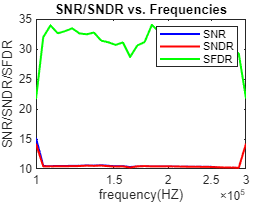

save('BigSet.mat', 'BigSet');
load('BigSet.mat')
figure
semilogx(BigSet(:,1), BigSet(:,2), 'b-', 'LineWidth', 1.5,"DisplayName","SNR");
hold on
semilogx(BigSet(:,1), BigSet(:,3), 'r-', 'LineWidth', 1.5, "DisplayName","SNDR");
semilogx(BigSet(:,1), BigSet(:,4), 'g-', 'LineWidth', 1.5, "DisplayName","SFDR");
hold off
xlabel("frequency(HZ)"); ylabel("SNR/SNDR/SFDR");
title("SNR/SNDR vs. Frequencies");
legend;